clc
clear
close all

%% Create trajectory for From Workspace blocks
Ts = 0.05;
t_end = 180;
t = (0:Ts:t_end)';

x_max = 80000;
h_max = 20000;

x_true_traj = linspace(0, x_max, length(t))';
s = x_true_traj / x_max;
y_true_traj = 4 * h_max * s .* (1 - s);

x_ts = timeseries(x_true_traj, t);
y_ts = timeseries(y_true_traj, t);

%% Monte Carlo settings
Nmc = 10;

%% Sensor noise standard deviations
sigma_radar_range  = 10;                 % metres
sigma_radar_bearing = deg2rad(0.5);      % radians
sigma_ir_bearing    = deg2rad(0.3);      % radians
sigma_ac_bearing    = deg2rad(2.0);      % radians

%% NIS clipping threshold for summary statistics
% Raw NIS is still stored, but clipped NIS is used for summary values
nis_clip_threshold = 100;

%% Measurement dimensions
m_radar = 2;   % range + radar bearing
m_ir    = 3;   % range + radar bearing + IR bearing
m_full  = 4;   % range + radar bearing + IR bearing + acoustic bearing

%% Chi-square bounds
alpha = 0.05;

lower_radar = chi2inv(alpha/2, m_radar);
upper_radar = chi2inv(1 - alpha/2, m_radar);

lower_ir = chi2inv(alpha/2, m_ir);
upper_ir = chi2inv(1 - alpha/2, m_ir);

lower_full = chi2inv(alpha/2, m_full);
upper_full = chi2inv(1 - alpha/2, m_full);

%% Preallocate storage

% Radar-only UKF
mean_nis_radar_all = zeros(Nmc,1);
inside_radar_all   = zeros(Nmc,1);
max_raw_radar_all  = zeros(Nmc,1);
max_clip_radar_all = zeros(Nmc,1);

% Radar + IR UKF
mean_nis_ir_all = zeros(Nmc,1);
inside_ir_all   = zeros(Nmc,1);
max_raw_ir_all  = zeros(Nmc,1);
max_clip_ir_all = zeros(Nmc,1);

% Full fusion UKF
mean_nis_full_all = zeros(Nmc,1);
inside_full_all   = zeros(Nmc,1);
max_raw_full_all  = zeros(Nmc,1);
max_clip_full_all = zeros(Nmc,1);

%% Store one example run for plotting
example_run = 1;

nis_radar_example_raw = [];
nis_radar_example_clip = [];

nis_ir_example_raw = [];
nis_ir_example_clip = [];

nis_full_example_raw = [];
nis_full_example_clip = [];

%% Monte Carlo loop
for k = 1:Nmc

    %% Change seeds each run
    seed_radar_range   = 100 + k;
    seed_radar_bearing = 200 + k;
    seed_ir            = 300 + k;
    seed_ac            = 400 + k;

    %% Run Simulink model
    simOut = sim("new_fusion_model", "SrcWorkspace", "current");

    %% Extract actual noisy sensor measurements
    r_meas      = simOut.range_meas.Data(:);
    theta_r_meas = simOut.bearing_meas.Data(:);
    theta_ir_meas = simOut.ir_meas.Data(:);
    theta_ac_meas = simOut.ac_meas.Data(:);

    %% ================================================================
    %  1) RADAR-ONLY UKF NIS
    %  Measurement vector: [range; radar bearing]
    %  Expected mean NIS: 2
    % ================================================================

    x_ukf_r = simOut.x_hat_ukf_r.Data(:);
    y_ukf_r = simOut.y_hat_ukf_r.Data(:);

    N_radar = min([length(x_ukf_r), length(y_ukf_r), ...
                   length(r_meas), length(theta_r_meas)]);

    x_r = x_ukf_r(1:N_radar);
    y_r = y_ukf_r(1:N_radar);

    r_radar = r_meas(1:N_radar);
    theta_radar = theta_r_meas(1:N_radar);

    % Predicted radar measurement from UKF estimate
    r_pred = sqrt(x_r.^2 + y_r.^2);
    theta_pred = atan2(y_r, x_r);

    % Innovation
    nu_range = r_radar - r_pred;
    nu_bearing = atan2(sin(theta_radar - theta_pred), ...
                       cos(theta_radar - theta_pred));

    % Approximate NIS
    nis_radar_raw = ...
        (nu_range.^2) / (sigma_radar_range^2) + ...
        (nu_bearing.^2) / (sigma_radar_bearing^2);

    % Clean invalid values
    nis_radar_raw = nis_radar_raw(isfinite(nis_radar_raw));

    % Store metrics
    if isempty(nis_radar_raw)
        mean_nis_radar_all(k) = NaN;
        inside_radar_all(k) = NaN;
        max_raw_radar_all(k) = NaN;
        max_clip_radar_all(k) = NaN;
    else
        max_raw_radar_all(k) = max(nis_radar_raw);

        nis_radar_clip = nis_radar_raw;
        nis_radar_clip(nis_radar_clip > nis_clip_threshold) = nis_clip_threshold;

        mean_nis_radar_all(k) = mean(nis_radar_clip);
        inside_radar_all(k) = 100 * mean(nis_radar_clip >= lower_radar & ...
                                         nis_radar_clip <= upper_radar);
        max_clip_radar_all(k) = max(nis_radar_clip);

        if k == example_run
            nis_radar_example_raw = nis_radar_raw;
            nis_radar_example_clip = nis_radar_clip;
        end
    end

    %% ================================================================
    %  2) RADAR + IR UKF NIS
    %  Measurement vector: [range; radar bearing; IR bearing]
    %  Expected mean NIS: 3
    % ================================================================

    x_ukf_ir = simOut.x_hat_ukf_ir.Data(:);
    y_ukf_ir = simOut.y_hat_ukf_ir.Data(:);

    N_ir = min([length(x_ukf_ir), length(y_ukf_ir), ...
                length(r_meas), length(theta_r_meas), length(theta_ir_meas)]);

    x_ir = x_ukf_ir(1:N_ir);
    y_ir = y_ukf_ir(1:N_ir);

    r_ir = r_meas(1:N_ir);
    theta_r_ir = theta_r_meas(1:N_ir);
    theta_ir = theta_ir_meas(1:N_ir);

    % Predicted measurements from UKF estimate
    r_pred_ir = sqrt(x_ir.^2 + y_ir.^2);
    theta_pred_ir = atan2(y_ir, x_ir);

    % Innovations
    nu_range_ir = r_ir - r_pred_ir;

    nu_radar_bearing_ir = atan2(sin(theta_r_ir - theta_pred_ir), ...
                                cos(theta_r_ir - theta_pred_ir));

    nu_ir_bearing = atan2(sin(theta_ir - theta_pred_ir), ...
                          cos(theta_ir - theta_pred_ir));

    % Approximate NIS
    nis_ir_raw = ...
        (nu_range_ir.^2) / (sigma_radar_range^2) + ...
        (nu_radar_bearing_ir.^2) / (sigma_radar_bearing^2) + ...
        (nu_ir_bearing.^2) / (sigma_ir_bearing^2);

    % Clean invalid values
    nis_ir_raw = nis_ir_raw(isfinite(nis_ir_raw));

    % Store metrics
    if isempty(nis_ir_raw)
        mean_nis_ir_all(k) = NaN;
        inside_ir_all(k) = NaN;
        max_raw_ir_all(k) = NaN;
        max_clip_ir_all(k) = NaN;
    else
        max_raw_ir_all(k) = max(nis_ir_raw);

        nis_ir_clip = nis_ir_raw;
        nis_ir_clip(nis_ir_clip > nis_clip_threshold) = nis_clip_threshold;

        mean_nis_ir_all(k) = mean(nis_ir_clip);
        inside_ir_all(k) = 100 * mean(nis_ir_clip >= lower_ir & ...
                                      nis_ir_clip <= upper_ir);
        max_clip_ir_all(k) = max(nis_ir_clip);

        if k == example_run
            nis_ir_example_raw = nis_ir_raw;
            nis_ir_example_clip = nis_ir_clip;
        end
    end

    %% ================================================================
    %  3) FULL FUSION UKF NIS
    %  Measurement vector:
    %  [range; radar bearing; IR bearing; acoustic bearing]
    %  Expected mean NIS: 4
    % ================================================================

    x_ukf_full = simOut.x_hat_ukf_full.Data(:);
    y_ukf_full = simOut.y_hat_ukf_full.Data(:);

    N_full = min([length(x_ukf_full), length(y_ukf_full), ...
                  length(r_meas), length(theta_r_meas), ...
                  length(theta_ir_meas), length(theta_ac_meas)]);

    x_full = x_ukf_full(1:N_full);
    y_full = y_ukf_full(1:N_full);

    r_full = r_meas(1:N_full);
    theta_r_full = theta_r_meas(1:N_full);
    theta_ir_full = theta_ir_meas(1:N_full);
    theta_ac_full = theta_ac_meas(1:N_full);

    % Predicted measurements from UKF estimate
    r_pred_full = sqrt(x_full.^2 + y_full.^2);
    theta_pred_full = atan2(y_full, x_full);

    % Innovations
    nu_range_full = r_full - r_pred_full;

    nu_radar_bearing_full = atan2(sin(theta_r_full - theta_pred_full), ...
                                  cos(theta_r_full - theta_pred_full));

    nu_ir_bearing_full = atan2(sin(theta_ir_full - theta_pred_full), ...
                               cos(theta_ir_full - theta_pred_full));

    nu_ac_bearing_full = atan2(sin(theta_ac_full - theta_pred_full), ...
                               cos(theta_ac_full - theta_pred_full));

    % Approximate NIS
    nis_full_raw = ...
        (nu_range_full.^2) / (sigma_radar_range^2) + ...
        (nu_radar_bearing_full.^2) / (sigma_radar_bearing^2) + ...
        (nu_ir_bearing_full.^2) / (sigma_ir_bearing^2) + ...
        (nu_ac_bearing_full.^2) / (sigma_ac_bearing^2);

    % Clean invalid values
    nis_full_raw = nis_full_raw(isfinite(nis_full_raw));

    % Store metrics
    if isempty(nis_full_raw)
        mean_nis_full_all(k) = NaN;
        inside_full_all(k) = NaN;
        max_raw_full_all(k) = NaN;
        max_clip_full_all(k) = NaN;
    else
        max_raw_full_all(k) = max(nis_full_raw);

        nis_full_clip = nis_full_raw;
        nis_full_clip(nis_full_clip > nis_clip_threshold) = nis_clip_threshold;

        mean_nis_full_all(k) = mean(nis_full_clip);
        inside_full_all(k) = 100 * mean(nis_full_clip >= lower_full & ...
                                        nis_full_clip <= upper_full);
        max_clip_full_all(k) = max(nis_full_clip);

        if k == example_run
            nis_full_example_raw = nis_full_raw;
            nis_full_example_clip = nis_full_clip;
        end
    end

    %% Print progress
    fprintf('Run %d / %d complete\n', k, Nmc);
    fprintf('Radar UKF mean NIS = %.3f | inside = %.2f%%\n', ...
        mean_nis_radar_all(k), inside_radar_all(k));
    fprintf('Radar + IR UKF mean NIS = %.3f | inside = %.2f%%\n', ...
        mean_nis_ir_all(k), inside_ir_all(k));
    fprintf('Full UKF mean NIS = %.3f | inside = %.2f%%\n\n', ...
        mean_nis_full_all(k), inside_full_all(k));

end

Run 1 / 10 complete


Radar UKF mean NIS = 1.496 | inside = 95.61%


Radar + IR UKF mean NIS = 2.432 | inside = 95.45%


Full UKF mean NIS = 3.397 | inside = 95.31%



Run 2 / 10 complete


Radar UKF mean NIS = 1.457 | inside = 95.25%


Radar + IR UKF mean NIS = 2.422 | inside = 94.70%


Full UKF mean NIS = 3.428 | inside = 94.53%



Run 3 / 10 complete


Radar UKF mean NIS = 1.478 | inside = 95.39%


Radar + IR UKF mean NIS = 2.433 | inside = 96.11%


Full UKF mean NIS = 3.512 | inside = 95.61%



Run 4 / 10 complete


Radar UKF mean NIS = 1.481 | inside = 95.72%


Radar + IR UKF mean NIS = 2.492 | inside = 95.78%


Full UKF mean NIS = 3.554 | inside = 96.14%



Run 5 / 10 complete


Radar UKF mean NIS = 1.457 | inside = 95.67%


Radar + IR UKF mean NIS = 2.445 | inside = 95.25%


Full UKF mean NIS = 3.477 | inside = 95.06%



Run 6 / 10 complete


Radar UKF mean NIS = 1.489 | inside = 95.81%


Radar + IR UKF mean NIS = 2.460 | inside = 95.56%


Full UKF mean NIS = 3.487 | inside = 94.67%



Run 7 / 10 complete


Radar UKF mean NIS = 1.463 | inside = 95.61%


Radar + IR UKF mean NIS = 2.511 | inside = 94.61%


Full UKF mean NIS = 3.431 | inside = 94.75%



Run 8 / 10 complete


Radar UKF mean NIS = 1.498 | inside = 95.56%


Radar + IR UKF mean NIS = 2.489 | inside = 95.42%


Full UKF mean NIS = 3.526 | inside = 95.31%



Run 9 / 10 complete


Radar UKF mean NIS = 1.574 | inside = 96.31%


Radar + IR UKF mean NIS = 2.607 | inside = 95.39%


Full UKF mean NIS = 3.644 | inside = 95.78%



Run 10 / 10 complete


Radar UKF mean NIS = 1.496 | inside = 95.70%


Radar + IR UKF mean NIS = 2.482 | inside = 94.78%


Full UKF mean NIS = 3.453 | inside = 94.36%




%% Remove invalid values
mean_nis_radar_valid = mean_nis_radar_all(isfinite(mean_nis_radar_all));
inside_radar_valid   = inside_radar_all(isfinite(inside_radar_all));
max_raw_radar_valid  = max_raw_radar_all(isfinite(max_raw_radar_all));
max_clip_radar_valid = max_clip_radar_all(isfinite(max_clip_radar_all));

mean_nis_ir_valid = mean_nis_ir_all(isfinite(mean_nis_ir_all));
inside_ir_valid   = inside_ir_all(isfinite(inside_ir_all));
max_raw_ir_valid  = max_raw_ir_all(isfinite(max_raw_ir_all));
max_clip_ir_valid = max_clip_ir_all(isfinite(max_clip_ir_all));

mean_nis_full_valid = mean_nis_full_all(isfinite(mean_nis_full_all));
inside_full_valid   = inside_full_all(isfinite(inside_full_all));
max_raw_full_valid  = max_raw_full_all(isfinite(max_raw_full_all));
max_clip_full_valid = max_clip_full_all(isfinite(max_clip_full_all));

%% Summary statistics
fprintf('\n==================================================\n');

fprintf('             MONTE CARLO NIS SUMMARY\n');

             MONTE CARLO NIS SUMMARY


fprintf('==================================================\n');


fprintf('\n--- Radar-only UKF ---\n');


--- Radar-only UKF ---


fprintf('Expected mean NIS = %d\n', m_radar);

Expected mean NIS = 2


fprintf('Mean of mean NIS = %.3f\n', mean(mean_nis_radar_valid));

Mean of mean NIS = 1.489


fprintf('Std of mean NIS = %.3f\n', std(mean_nis_radar_valid));

Std of mean NIS = 0.034


fprintf('Mean %% inside 95%% bounds = %.2f%%\n', mean(inside_radar_valid));

Mean % inside 95% bounds = 95.66%


fprintf('Std %% inside 95%% bounds = %.2f%%\n', std(inside_radar_valid));

Std % inside 95% bounds = 0.28%


fprintf('Mean raw max NIS = %.3f\n', mean(max_raw_radar_valid));

Mean raw max NIS = 851.301


fprintf('Mean clipped max NIS = %.3f\n', mean(max_clip_radar_valid));

Mean clipped max NIS = 65.917


fprintf('95%% bounds = [%.3f, %.3f]\n', lower_radar, upper_radar);

95% bounds = [0.051, 7.378]



fprintf('\n--- Radar + IR UKF ---\n');


--- Radar + IR UKF ---


fprintf('Expected mean NIS = %d\n', m_ir);

Expected mean NIS = 3


fprintf('Mean of mean NIS = %.3f\n', mean(mean_nis_ir_valid));

Mean of mean NIS = 2.477


fprintf('Std of mean NIS = %.3f\n', std(mean_nis_ir_valid));

Std of mean NIS = 0.055


fprintf('Mean %% inside 95%% bounds = %.2f%%\n', mean(inside_ir_valid));

Mean % inside 95% bounds = 95.30%


fprintf('Std %% inside 95%% bounds = %.2f%%\n', std(inside_ir_valid));

Std % inside 95% bounds = 0.48%


fprintf('Mean raw max NIS = %.3f\n', mean(max_raw_ir_valid));

Mean raw max NIS = 3051.704


fprintf('Mean clipped max NIS = %.3f\n', mean(max_clip_ir_valid));

Mean clipped max NIS = 70.238


fprintf('95%% bounds = [%.3f, %.3f]\n', lower_ir, upper_ir);

95% bounds = [0.216, 9.348]



fprintf('\n--- Full Fusion UKF ---\n');


--- Full Fusion UKF ---


fprintf('Expected mean NIS = %d\n', m_full);

Expected mean NIS = 4


fprintf('Mean of mean NIS = %.3f\n', mean(mean_nis_full_valid));

Mean of mean NIS = 3.491


fprintf('Std of mean NIS = %.3f\n', std(mean_nis_full_valid));

Std of mean NIS = 0.072


fprintf('Mean %% inside 95%% bounds = %.2f%%\n', mean(inside_full_valid));

Mean % inside 95% bounds = 95.15%


fprintf('Std %% inside 95%% bounds = %.2f%%\n', std(inside_full_valid));

Std % inside 95% bounds = 0.58%


fprintf('Mean raw max NIS = %.3f\n', mean(max_raw_full_valid));

Mean raw max NIS = 42060.394


fprintf('Mean clipped max NIS = %.3f\n', mean(max_clip_full_valid));

Mean clipped max NIS = 76.991


fprintf('95%% bounds = [%.3f, %.3f]\n', lower_full, upper_full);

95% bounds = [0.484, 11.143]



%% Create summary table
Method = {'UKF Radar'; 'UKF Radar + IR'; 'UKF Full Fusion'};

Expected_Mean_NIS = [m_radar; m_ir; m_full];

Mean_NIS = [mean(mean_nis_radar_valid); ...
            mean(mean_nis_ir_valid); ...
            mean(mean_nis_full_valid)];

Std_Mean_NIS = [std(mean_nis_radar_valid); ...
                std(mean_nis_ir_valid); ...
                std(mean_nis_full_valid)];

Mean_Inside_Bounds_Percent = [mean(inside_radar_valid); ...
                              mean(inside_ir_valid); ...
                              mean(inside_full_valid)];

Std_Inside_Bounds_Percent = [std(inside_radar_valid); ...
                             std(inside_ir_valid); ...
                             std(inside_full_valid)];

Mean_Raw_Max_NIS = [mean(max_raw_radar_valid); ...
                    mean(max_raw_ir_valid); ...
                    mean(max_raw_full_valid)];

Mean_Clipped_Max_NIS = [mean(max_clip_radar_valid); ...
                        mean(max_clip_ir_valid); ...
                        mean(max_clip_full_valid)];

NIS_Summary_Table = table(Method, Expected_Mean_NIS, Mean_NIS, Std_Mean_NIS, ...
    Mean_Inside_Bounds_Percent, Std_Inside_Bounds_Percent, ...
    Mean_Raw_Max_NIS, Mean_Clipped_Max_NIS);

disp(NIS_Summary_Table);

          Method           Expected_Mean_NIS    Mean_NIS    Std_Mean_NIS    Mean_Inside_Bounds_Percent    Std_Inside_Bounds_Percent    Mean_Raw_Max_NIS    Mean_Clipped_Max_NIS
    ___________________    _________________    ________    ____________    __________________________    _________________________    ________________    ____________________

    {'UKF Radar'      }            2              1.489        0.03391                95.662                       0.27887                   851.3                65.917       
    {'UKF Radar + IR' }            3             2.4774       0.054603                95.304                       0.48409                  3051.7                70.238       
    {'UKF Full Fusion'}

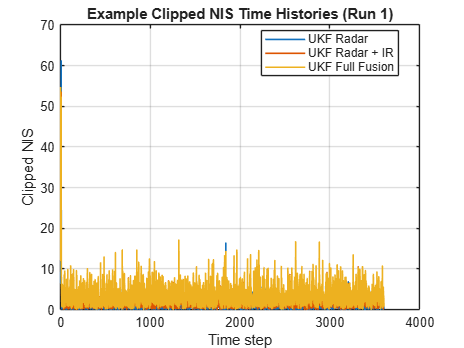


%% Plot 1: Example clipped NIS time histories
figure
plot(nis_radar_example_clip, 'LineWidth', 1.2)
hold on
plot(nis_ir_example_clip, 'LineWidth', 1.2)
plot(nis_full_example_clip, 'LineWidth', 1.2)
grid on
xlabel('Time step')
ylabel('Clipped NIS')
title(sprintf('Example Clipped NIS Time Histories (Run %d)', example_run))
legend('UKF Radar', 'UKF Radar + IR', 'UKF Full Fusion', 'Location', 'best')

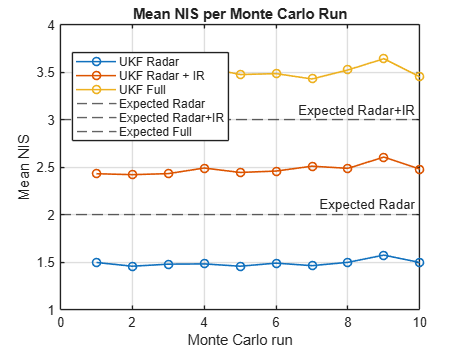


%% Plot 2: Mean NIS per run for all UKF configurations
figure
plot(mean_nis_radar_all, 'o-', 'LineWidth', 1.2)
hold on
plot(mean_nis_ir_all, 'o-', 'LineWidth', 1.2)
plot(mean_nis_full_all, 'o-', 'LineWidth', 1.2)
yline(m_radar, '--', 'Expected Radar')
yline(m_ir, '--', 'Expected Radar+IR')
yline(m_full, '--', 'Expected Full')
grid on
xlabel('Monte Carlo run')
ylabel('Mean NIS')
title('Mean NIS per Monte Carlo Run')
legend('UKF Radar', 'UKF Radar + IR', 'UKF Full', ...
       'Expected Radar', 'Expected Radar+IR', 'Expected Full', ...
       'Location', 'best')

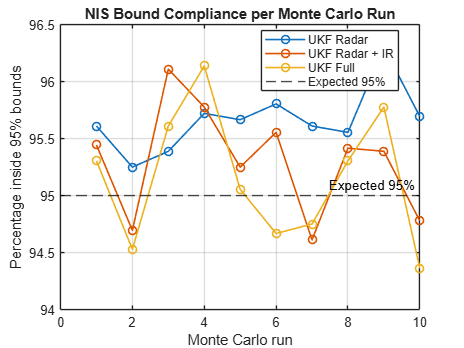


%% Plot 3: Percentage inside bounds per run
figure
plot(inside_radar_all, 'o-', 'LineWidth', 1.2)
hold on
plot(inside_ir_all, 'o-', 'LineWidth', 1.2)
plot(inside_full_all, 'o-', 'LineWidth', 1.2)
yline(95, '--k', 'Expected 95%')
grid on
xlabel('Monte Carlo run')
ylabel('Percentage inside 95% bounds')
title('NIS Bound Compliance per Monte Carlo Run')
legend('UKF Radar', 'UKF Radar + IR', 'UKF Full', ...
       'Expected 95%', 'Location', 'best')

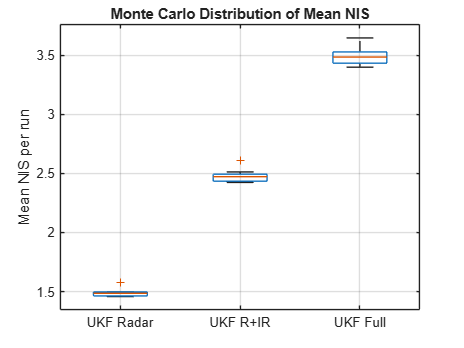


%% Plot 4: Boxplot of mean NIS
figure
boxplot([mean_nis_radar_all, mean_nis_ir_all, mean_nis_full_all], ...
    'Labels', {'UKF Radar', 'UKF R+IR', 'UKF Full'})
ylabel('Mean NIS per run')
title('Monte Carlo Distribution of Mean NIS')
grid on

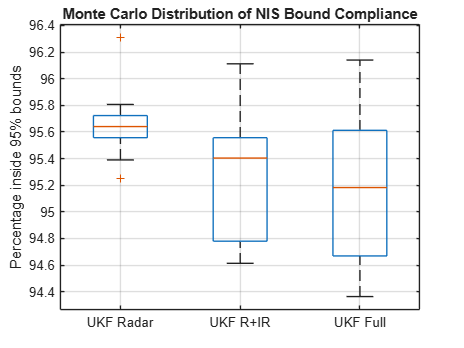


%% Plot 5: Boxplot of percentage inside bounds
figure
boxplot([inside_radar_all, inside_ir_all, inside_full_all], ...
    'Labels', {'UKF Radar', 'UKF R+IR', 'UKF Full'})
ylabel('Percentage inside 95% bounds')
title('Monte Carlo Distribution of NIS Bound Compliance')
grid on